close all; clear all;
% -- GRID PROPERTIES -------------------------------------------
N_medium=650*94*94;
N_coarse=515*75*75;
N_verycoarse=410*60*60;

N=[N_medium;N_coarse;N_verycoarse];

% -- TIME PROPERTIES -------------------------------------------
t_medium=0.608; %[s]
t_coarse=0.316; %[s]
t_verycoarse=0.145; %[s]

t=[t_medium;t_coarse;t_verycoarse];

% -- MEMORY PROPERTIES -----------------------------------------
M_medium=484; %[MB]
M_coarse=246; %[MB]
M_verycoarse=124; %[MB]

M=[M_medium;M_coarse;M_verycoarse];

N_DNS=686608*84682*84682;

at=N\t;
bt=t(1)-N(1)*at;
t_DNS=at*N_DNS+bt

t_DNS = 5.2241e+08

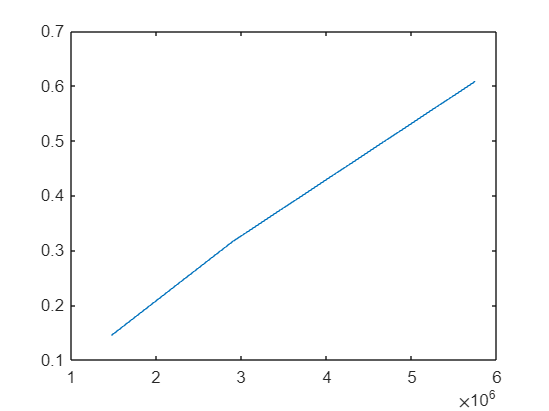

figure;
plot(N,t);



am=N\M;
bm=M(1)-N(1)*am;
M_DNS=am*N_DNS+bm

M_DNS = 4.1547e+11

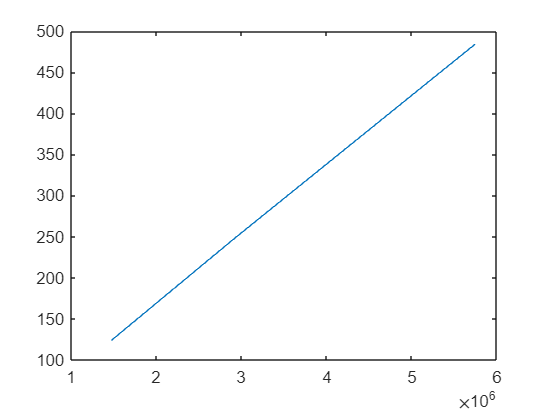

figure;
plot(N,M);